% Clear workspace
clear
clc

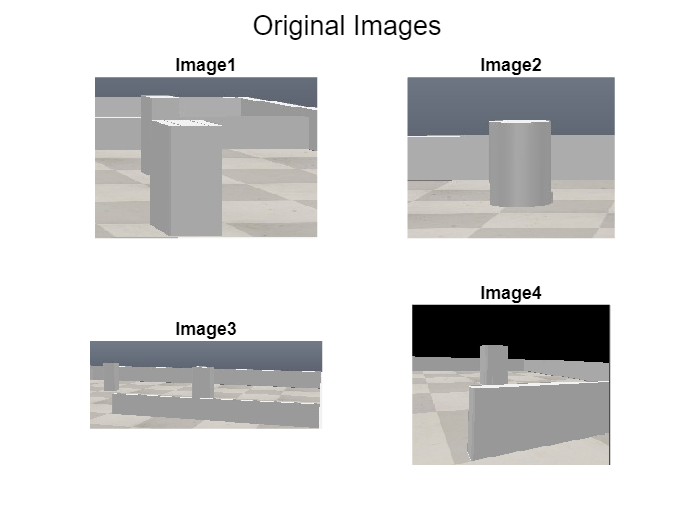

% Read Image
img1 = imread('img1.jpg');
img2 = imread('img2.jpg');
img3 = imread('img3.jpg');
img4 = imread('img4.jpg');

% Display Original Images
figure, subplot(2,2,1), imshow(img1), title('Image1')
  subplot(2,2,2), imshow(img2), title('Image2')
  subplot(2,2,3), imshow(img3), title('Image3')
  subplot(2,2,4), imshow(img4), title('Image4')
  sgtitle('Original Images');

% Convert Image to grayscale
img2gray1 = rgb2gray(img1);
img2gray2 = rgb2gray(img2);
img2gray3 = rgb2gray(img3);
img2gray4 = rgb2gray(img4);

% Apply a median filter to reduce noise
img_median1 = medfilt3(img2gray1);
img_median2 = medfilt3(img2gray2);
img_median3 = medfilt3(img2gray3);
img_median4 = medfilt3(img2gray4);

% Apply a Gaussian filter to further reduce noise
img_gaussian1 = imgaussfilt(img_median1);
img_gaussian2 = imgaussfilt(img_median2);
img_gaussian3 = imgaussfilt(img_median3);
img_gaussian4 = imgaussfilt(img_median4);

% Apply histogram equalization to enhance the contrast
img_equalized1 = histeq(img_gaussian1);
img_equalized2 = histeq(img_gaussian2);
img_equalized3 = histeq(img_gaussian3);
img_equalized4 = histeq(img_gaussian4);

% Apply an unsharp mask filter to sharpen the edges
img_unsharp1 = imsharpen(img_equalized1);
img_unsharp2 = imsharpen(img_equalized2);
img_unsharp3 = imsharpen(img_equalized3);
img_unsharp4 = imsharpen(img_equalized4);

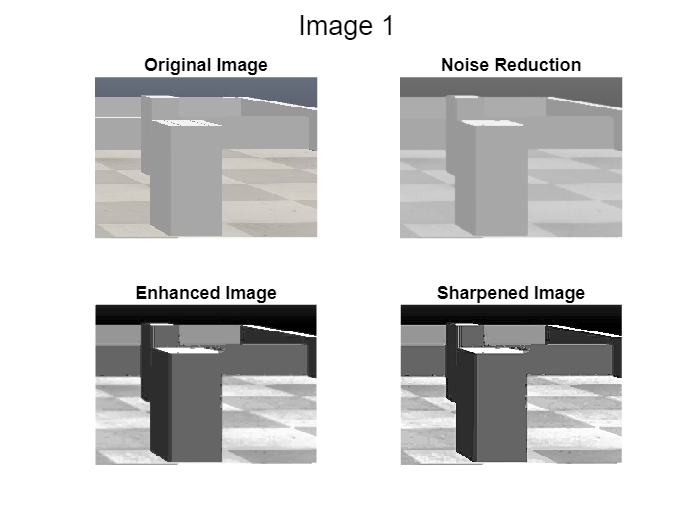

% Display original and preprocessed images
figure, subplot(2,2,1), imshow(img1), title('Original Image')
  subplot(2,2,2), imshow(img_gaussian1), title('Noise Reduction')
  subplot(2,2,3), imshow(img_equalized1), title('Enhanced Image')
  subplot(2,2,4), imshow(img_unsharp1), title('Sharpened Image')
  sgtitle('Image 1');  

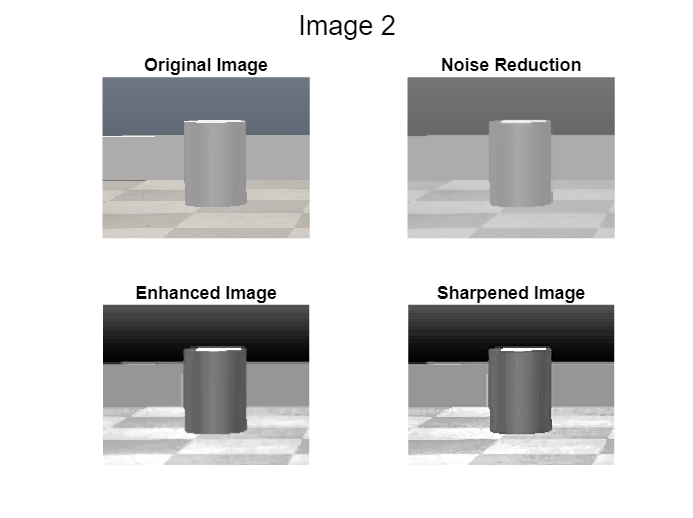


figure, subplot(2,2,1), imshow(img2), title('Original Image')
  subplot(2,2,2), imshow(img_gaussian2), title('Noise Reduction')
  subplot(2,2,3), imshow(img_equalized2), title('Enhanced Image')
  subplot(2,2,4), imshow(img_unsharp2), title('Sharpened Image')
  sgtitle('Image 2');

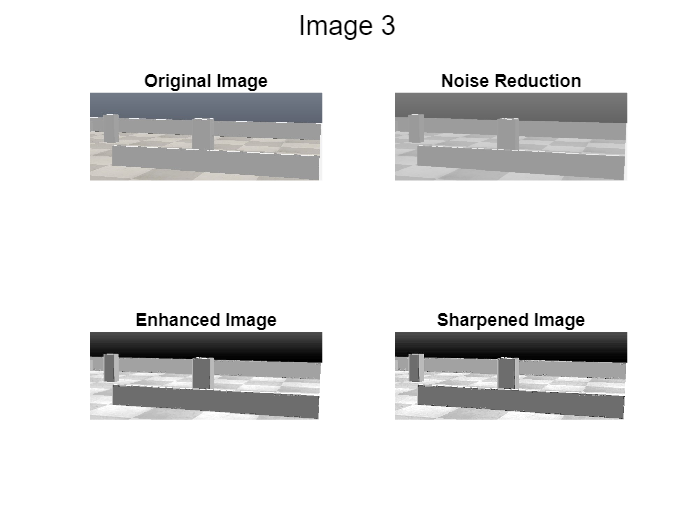


figure, subplot(2,2,1), imshow(img3), title('Original Image')
  subplot(2,2,2), imshow(img_gaussian3), title('Noise Reduction')
  subplot(2,2,3), imshow(img_equalized3), title('Enhanced Image')
  subplot(2,2,4), imshow(img_unsharp3), title('Sharpened Image')
  sgtitle('Image 3');

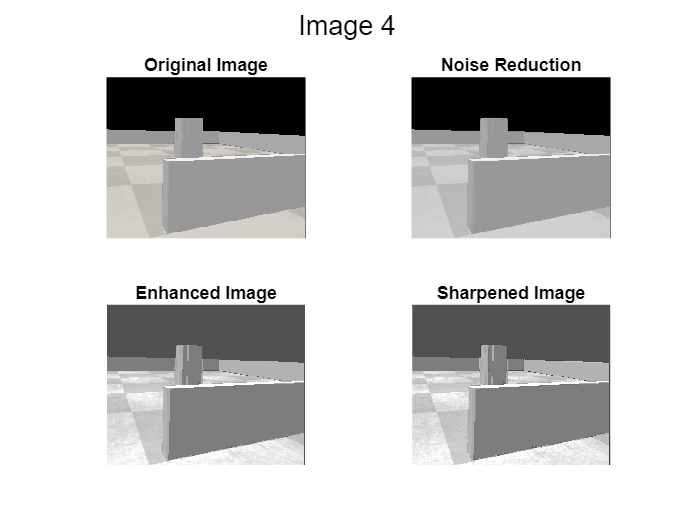


figure, subplot(2,2,1), imshow(img4), title('Original Image')
  subplot(2,2,2), imshow(img_gaussian4), title('Noise Reduction')
  subplot(2,2,3), imshow(img_equalized4), title('Enhanced Image')
  subplot(2,2,4), imshow(img_unsharp4), title('Sharpened Image')
  sgtitle('Image 4');

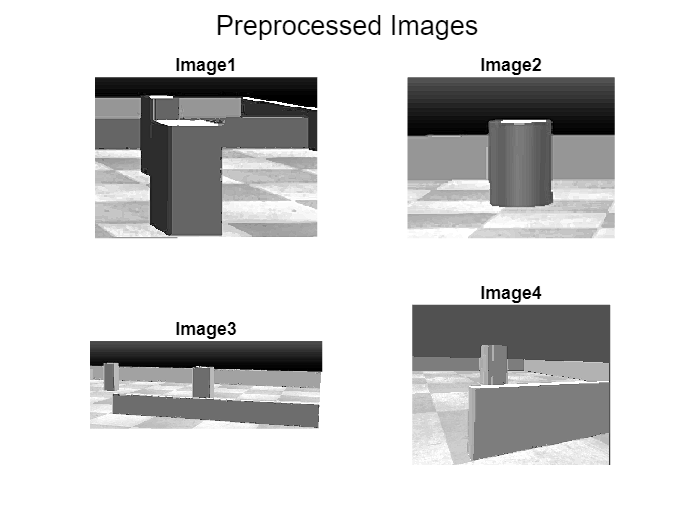

% Display Preprocessed Images
figure, subplot(2,2,1), imshow(img_unsharp1), title('Image1')
  subplot(2,2,2), imshow(img_unsharp2), title('Image2')
  subplot(2,2,3), imshow(img_unsharp3), title('Image3')
  subplot(2,2,4), imshow(img_unsharp4), title('Image4')
  sgtitle('Preprocessed Images');

% Apply Canny filter for edge detection
img_edge1 = edge(img_unsharp1,'canny');
img_edge2 = edge(img_unsharp2,'canny');
img_edge3 = edge(img_unsharp3,'canny');
img_edge4 = edge(img_unsharp4,'canny');

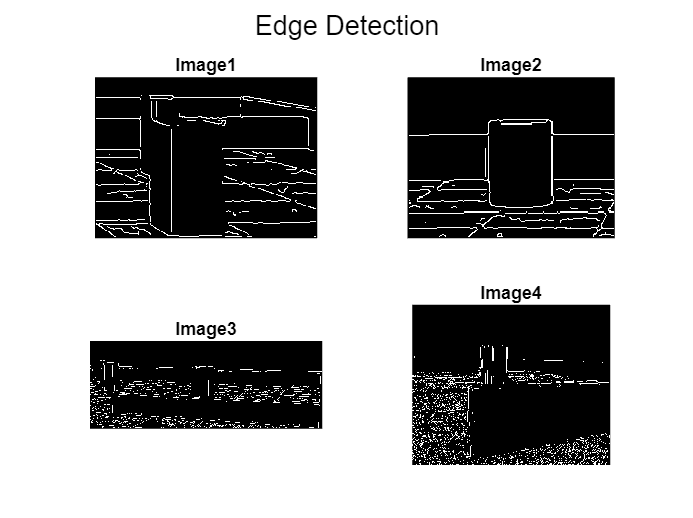

% Display Edge Detection
figure, subplot(2,2,1), imshow(img_edge1), title('Image1')
  subplot(2,2,2), imshow(img_edge2), title('Image2')
  subplot(2,2,3), imshow(img_edge3), title('Image3')
  subplot(2,2,4), imshow(img_edge4), title('Image4')
  sgtitle('Edge Detection');

% Apply OTSU Thresholding for region based segmentation
[counts,x1] = imhist(img_unsharp1,16);
T1 = otsuthresh(counts);

[counts,x2] = imhist(img_unsharp2,16);
T2 = otsuthresh(counts);

[counts,x3] = imhist(img_unsharp3,16);
T3 = otsuthresh(counts);

[counts,x4] = imhist(img_unsharp4,16);
T4 = otsuthresh(counts);

img_OTSU1 = imbinarize(img_unsharp1,T1);
img_OTSU2 = imbinarize(img_unsharp2,T2);
img_OTSU3 = imbinarize(img_unsharp3,T3);
img_OTSU4 = imbinarize(img_unsharp4,T4);

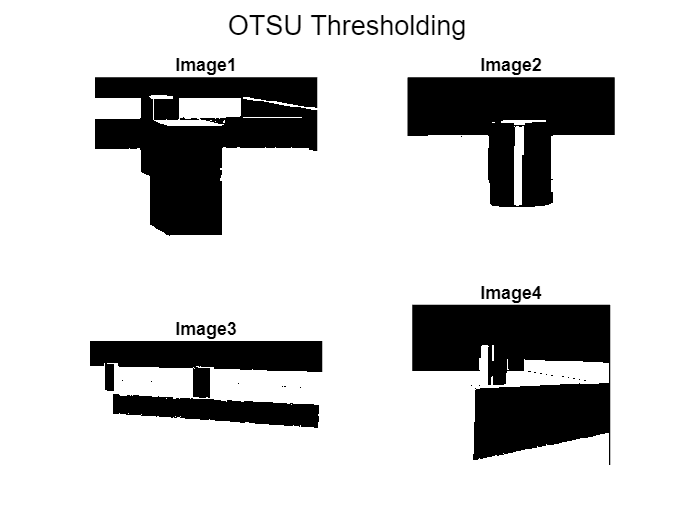

% Display Region Based Segmentation
figure, subplot(2,2,1), imshow(img_OTSU1), title('Image1')
  subplot(2,2,2), imshow(img_OTSU2), title('Image2')
  subplot(2,2,3), imshow(img_OTSU3), title('Image3')
  subplot(2,2,4), imshow(img_OTSU4), title('Image4')
  sgtitle('OTSU Thresholding');